# 1. Meshgrid test - MATLAB

% Run the Python notebook first to export inputs.mat, then run all.
% This file performs only the reference/grid calculations from 
% KLJCmainsv22.m (lines 45-97 and 132-133 in the current source).
%
% Lengths: mm. Input frequencies: GHz. Beam voltage: kV. Current: A.
% This is a one-dimensional longitudinal grid. Radial plots are schematics.
% meshgrid_test.m and meshgrid_test.mlx contain the same test: run either one.

% Live Editor runs temporary helper code; use the open notebook's filename.
test_file = mfilename('fullpath');
if isempty(test_file) || contains(test_file, 'LiveEditorEvaluationHelper')
    test_file = matlab.desktop.editor.getActiveFilename;
end
test_directory = fileparts(test_file);
input_file = fullfile(test_directory, 'inputs.mat');
assert(isfile(input_file), ...
    'Cannot find inputs.mat at: %s\nRun meshgrid_test.ipynb to export it.', input_file);
load(input_file);
assert(rc ~= 0 && yd == 0, 'This test covers the cylindrical-beam branch.');

% Y0 is already one-based in inputs.mat: do not add 1 again.
% Constants below come from KLJCmainsv22.m, not from the Python export.

## 2. Reference beam quantities and grid - Original lines 45-97

The following block is copied from KLJCmainsv22.m, including its comments. Only syntax correction: the source's Nesz=zeros(length(zi),2)N; has a stray N. It is removed below so the test can run; the source is unchanged.

CALCULATE THE REFERENCE PAMAMETER

Nt = double(Nt)

Nt = 128


Iz0=1/2/pi*2*pi/Nt*sum(Izt(Y0)); % A, araverge emission current
I0=abs(Iz0);
U0=1/2/pi*2*pi/Nt*sum(Izt(Y0).*Ut(Y0))/Iz0;% kV, average emission voltage

% constant
c=299792458;  % m/s, light speed
etom=-1.7588E11;  % C/kg, charge to mass of electron
eta0=4E-7*pi*c; % ohm, wave impendance of TEM

esign=sign(-etom); % for negative charged paticles, esign=1; for postive charged particles, esign=-1
etom=abs(etom);

etom = double(etom);
c    = double(c);
U0   = double(U0);

s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
vetoc=(1-(1+etom/c/c*Ut*1E3).^(-2)).^(1/2); % vet/c
vn1=0*vetoc;
vn1(Y0)=s./vetoc(Y0); % ve0/ve(t) at the entrance


w=2*pi*f*1E9;  % rad/s, angular frequency of operating
w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant
k0=w0/c/1000;   % 1/mm,  wave number at resonant freqency
Lsb=pi*ones(1,Nc); % phaseshift beta0*Ls from the entrance of output cavity at resonant freqency

gama=1+etom*U0*1000/c/c; % Lorentz factor
betae=w/c/s/1000;  % 1/mm, betae at operating freqency

Nz = double(Nz);
dz=2*pi/betae/Nz;  % mm,

dz=L/floor(L/dz); % mm, increment of z
dz = double(dz);
zi=(z0:dz:z0+L)'; % mm, z position sequence

rcvs=interp1(rcv(1,:),rcv(2,:)*rc,zi,'linear','extrap'); % mm, tunnel radius sequence

if rc~=0  % for cylindrical beam
    dN=floor(factorregion*rc/2.40483/dz); % N dz interval is included to calculate the local SP
    Nesz=zeros(length(zi),2);
    for k=1:length(zi)
        Nesz(k,1)=max(1,k-dN); % min order of interval
        Nesz(k,2)=min(length(zi),k+dN); % max order of interval
    end
else  % for sheet beam

end

## 3. Normalized coordinates - Original lines 132-133

The intervening field-map block is outside the scope of this mesh test.

z=betae*zi; % normalized z position
dt=betae*dz; % normalized time step & normalized position step, in real time step=position step/injecting velocity of electron

## 4. Inspect the calculated quantities

k0 is a vacuum wavenumber at f0; betae uses beam speed at f. rcvs is the physical tube radius sampled on zi.

% Test-only helper for the spacing plot; not inserted into the source block.
dz_requested=2*pi/betae/Nz;

Variable = {'Iz0'; 'I0'; 'U0'; 's'; 'gama'; 'w'; 'betae'; ...
    'length(zi)'; 'dz_requested'; 'dz'; 'dt'; 'dt/w'; 'dN'};
Value = [Iz0; I0; U0; s; gama; w; betae; length(zi); ...
    dz_requested; dz; dt; dt/w; dN];
Unit = {'A'; 'A'; 'kV'; '1'; '1'; 'rad/s'; '1/mm'; ...
    'nodes'; 'mm'; 'mm'; '1'; 's'; 'intervals'};
disp(table(Variable, Value, Unit));

        Variable          Value           Unit     
    ________________    __________    _____________

    {'Iz0'         }           -16    {'A'        }
    {'I0'          }            16    {'A'        }
    {'U0'          }           180    {'kV'       }
    {'s'           }       0.67315    {'1'        }
    {'gama'        }        1.3522    {'1'        }
    {'w'           }    6.2832e+09    {'rad/s'    }
    {'betae'       }      0.031135    {'1/mm'     }
    {'length(zi)'  }          3806    {'nodes'    }
    {'dz_requested'}        0.7883    {'mm'       }
    {'dz'          }       0.78844    {'mm'       }
    {'dt'          }      0.024548    {'1'        }
    {'dt/w'        }    3.9069e-12    {'s'        }
    {'dN'          }            52    {'intervals'}



disp('w0 [rad/s]:'); disp(w0);

w0 [rad/s]:
   1.0e+09 *

    6.2832    6.3209    6.3837    6.4717    6.2832



disp('k0 [1/mm]:'); disp(k0);

k0 [1/mm]:
    0.0210    0.0211    0.0213    0.0216    0.0210



fprintf('vetoc range: %.9g to %.9g; vn1 range: %.9g to %.9g\n', ...
    min(vetoc), max(vetoc), min(vn1), max(vn1));

vetoc range: 0.67314584 to 0.67314584; vn1 range: 1 to 1


## 5. Geometry and physical/normalized coordinates

Cavity-center markers are not cavity wall shapes or field maps. rcv(1,:) is the physical axis; rcv(2,:) is the radius divided by rc.

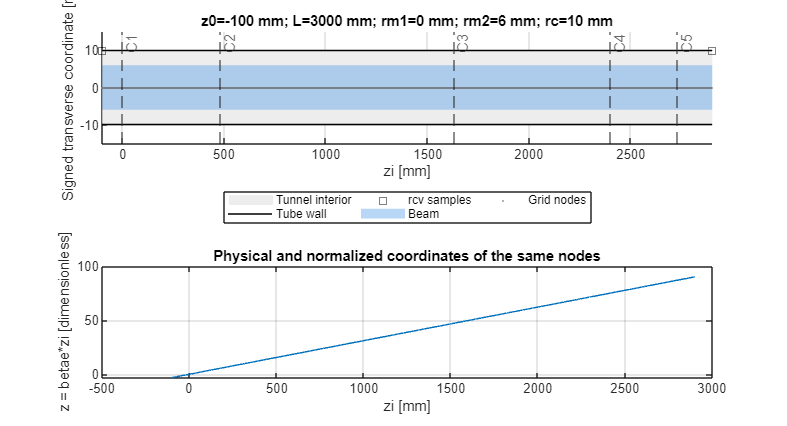

figure('Name', 'Meshgrid: geometry', 'Position', [100 100 1200 650]);
tiledlayout(2,1);
nexttile;
hold on;
fill([zi; flipud(zi)], [rcvs; -flipud(rcvs)], [0.93 0.93 0.93], ...
    'EdgeColor', 'none', 'DisplayName', 'Tunnel interior');
plot(zi, rcvs, 'k-', 'DisplayName', 'Tube wall');
plot(zi, -rcvs, 'k-', 'HandleVisibility', 'off');
plot(rcv(1,:), rc*rcv(2,:), 'ks', 'DisplayName', 'rcv samples');
fill([z0 z0+L z0+L z0], [rm1 rm1 rm2 rm2], [0.3 0.6 0.9], ...
    'FaceAlpha', 0.4, 'EdgeColor', 'none', 'DisplayName', 'Beam');
fill([z0 z0+L z0+L z0], [-rm2 -rm2 -rm1 -rm1], [0.3 0.6 0.9], ...
    'FaceAlpha', 0.4, 'EdgeColor', 'none', 'HandleVisibility', 'off');
plot(zi, zeros(size(zi)), '.', 'Color', [0.4 0.4 0.4], ...
    'MarkerSize', 2, 'DisplayName', 'Grid nodes');
for k=1:Nc
    xline(zshift(k), '--', sprintf('C%d', k), 'HandleVisibility', 'off');
end
xlim([z0 z0+L]);
ylim(1.5*[-max(rcvs) max(rcvs)]);
xlabel('zi [mm]'); ylabel('Signed transverse coordinate [mm]');
title(sprintf('z0=%g mm; L=%g mm; rm1=%g mm; rm2=%g mm; rc=%g mm', ...
    z0, L, rm1, rm2, rc));
legend('Location', 'southoutside', 'NumColumns', 3);
grid on;

nexttile;
plot(zi, z);
xlabel('zi [mm]'); ylabel('z = betae*zi [dimensionless]');
title('Physical and normalized coordinates of the same nodes');
grid on;

## 6. Node spacing and index zoom

MATLAB kz starts at 1. The equivalent Python node index is kz-1. Use the same central node as in the Python notebook.

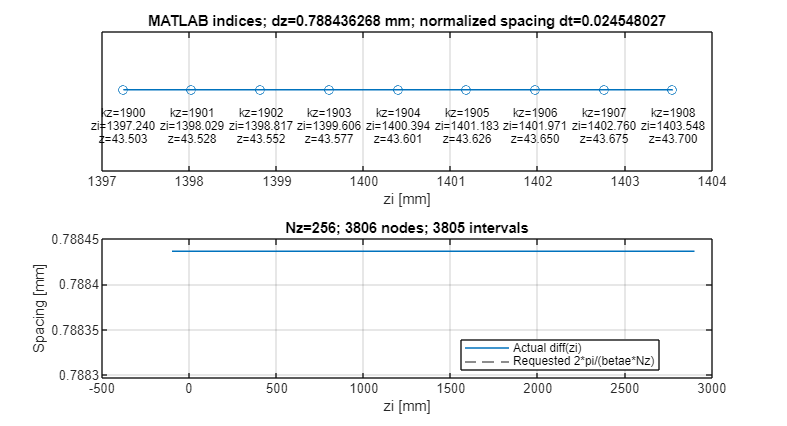

kz=floor(length(zi)/2)+1;
indices=max(1,kz-4):min(length(zi),kz+4);
figure('Name', 'Meshgrid: spacing', 'Position', [100 100 1200 650]);
tiledlayout(2,1);
nexttile;
plot(zi(indices), zeros(size(indices)), 'o-');
hold on;
for k=indices
    text(zi(k), -0.15, sprintf('kz=%d\nzi=%.3f\nz=%.3f', k, zi(k), z(k)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 8);
end
ylim([-0.7 0.5]); yticks([]);
xlabel('zi [mm]');
title(sprintf('MATLAB indices; dz=%.9g mm; normalized spacing dt=%.9g', dz, dt));
grid on;

nexttile;
plot(zi(1:end-1), diff(zi), 'DisplayName', 'Actual diff(zi)');
hold on;
yline(dz_requested, '--', 'DisplayName', 'Requested 2*pi/(betae*Nz)');
xlabel('zi [mm]'); ylabel('Spacing [mm]');
title(sprintf('Nz=%d; %d nodes; %d intervals', Nz, length(zi), length(zi)-1));
legend('Location', 'best');
grid on;

## 7. Space-charge source windows

MATLAB Nesz gives one-based, inclusive first and last indices. A source window is zi(Nesz(kz,1):Nesz(kz,2)). Python [0,53] corresponds to MATLAB [1,53]: both include 53 nodes. This does not compute space charge or add the upstream prefill grid zp.

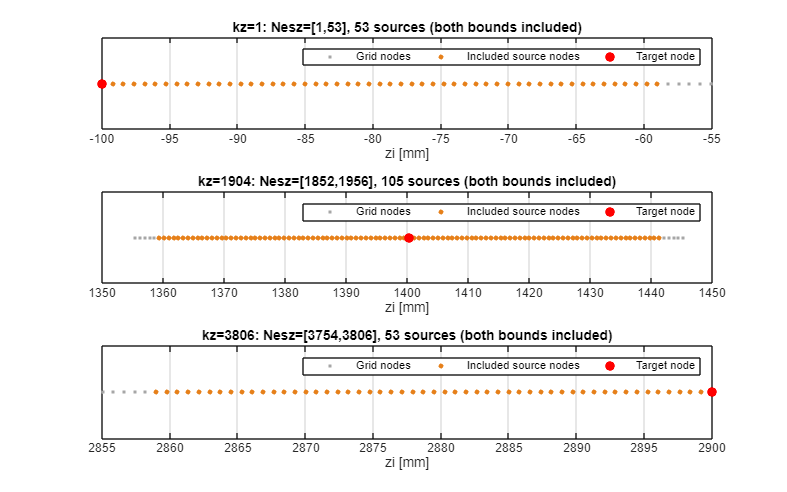

figure('Name', 'Meshgrid: source windows', 'Position', [100 100 1200 750]);
tiledlayout(3,1);
for kz=[1 floor(length(zi)/2)+1 length(zi)]
    first=Nesz(kz,1);
    last=Nesz(kz,2);
    nearby=max(1,first-5):min(length(zi),last+5);
    nexttile;
    plot(zi(nearby), zeros(size(nearby)), '.', 'Color', [0.65 0.65 0.65], ...
        'DisplayName', 'Grid nodes');
    hold on;
    plot(zi(first:last), zeros(last-first+1,1), '.', 'Color', [0.9 0.5 0.1], ...
        'MarkerSize', 10, 'DisplayName', 'Included source nodes');
    plot(zi(kz), 0, 'ro', 'MarkerFaceColor', 'r', 'DisplayName', 'Target node');
    ylim([-0.5 0.5]); yticks([]);
    xlabel('zi [mm]');
    title(sprintf('kz=%d: Nesz=[%d,%d], %d sources (both bounds included)', ...
        kz, first, last, last-first+1));
    legend('Location', 'northeast', 'NumColumns', 3);
    grid on;
end

fprintf('dN=%d; interior half-width dN*dz=%.9g mm\n', dN, dN*dz);

dN=52; interior half-width dN*dz=40.9986859 mm


## 8. Emission and entrance phases

t0 labels departure phase; tn1 is entrance phase. They coincide in this test because Python assigned tn1=t0. Phase-sample spacing 2*pi/Nt is independent of the spatial grid step dt.

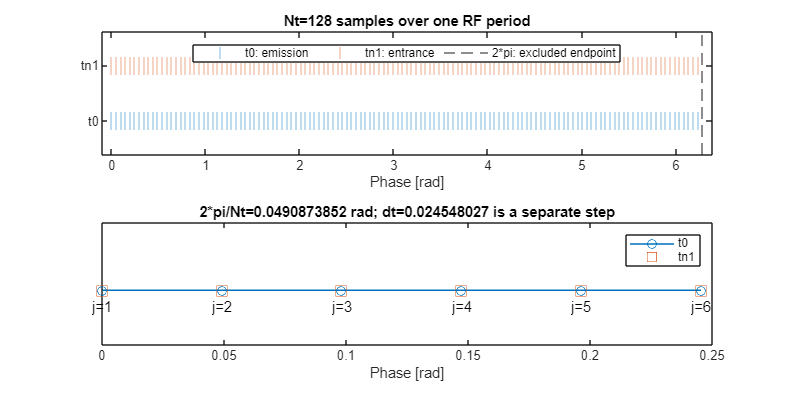

figure('Name', 'Meshgrid: phases', 'Position', [100 100 1200 600]);
tiledlayout(2,1);
nexttile;
plot(t0, zeros(size(t0)), '|', 'MarkerSize', 12, 'DisplayName', 't0: emission');
hold on;
plot(tn1, ones(size(tn1)), '|', 'MarkerSize', 12, 'DisplayName', 'tn1: entrance');
xline(2*pi, '--', 'DisplayName', '2*pi: excluded endpoint');
xlim([-0.1 2*pi+0.1]); ylim([-0.6 1.6]);
yticks([0 1]); yticklabels({'t0','tn1'});
xlabel('Phase [rad]');
title(sprintf('Nt=%d samples over one RF period', Nt));
legend('Location', 'north', 'NumColumns', 3);

nexttile;
indices=1:min(6,Nt);
plot(t0(indices), zeros(size(indices)), 'o-', 'DisplayName', 't0');
hold on;
plot(tn1(indices), zeros(size(indices)), 's', 'MarkerSize', 9, ...
    'DisplayName', 'tn1');
for k=indices
    text(t0(k), -0.12, sprintf('j=%d', k), 'HorizontalAlignment', 'center');
end
ylim([-0.4 0.5]); yticks([]);
xlabel('Phase [rad]');
title(sprintf('2*pi/Nt=%.9g rad; dt=%.9g is a separate step', 2*pi/Nt, dt));
legend('Location', 'northeast');

## 9. Basic MATLAB consistency checks

Internal checks only. No Python result is loaded or compared here.

assert(length(zi)==floor(L/dz_requested)+1);
assert(max(abs(zi([1 end])-[z0; z0+L])) < 1e-10);
assert(max(abs(diff(zi)-dz)) < 1e-10);
assert(max(abs(diff(z)-dt)) < 1e-10);
indices=(1:length(zi))';
assert(isequal(Nesz(:,1),max(1,indices-dN)));
assert(isequal(Nesz(:,2),min(length(zi),indices+dN)));
disp('MATLAB consistency checks passed. Cross-language comparison is a separate step.');

MATLAB consistency checks passed. Cross-language comparison is a separate step.


## 10. Export MATLAB results

Save the same 18 quantities as python_results.mat, in ordinary MAT format. Keep native MATLAB vector orientations and one-based inclusive Nesz. The future comparison script will account for these conventions. Running this section overwrites matlab_results.mat beside this script.

save(fullfile(test_directory,'matlab_results.mat'), ...
    'Iz0','I0','U0','s','vetoc','vn1','gama', ...
    'w','w0','k0','betae','dz','zi','z','dt','rcvs','dN','Nesz','-v7');
fprintf('Saved: %s\n', fullfile(test_directory,'matlab_results.mat'));

Saved: C:\Users\lsito\Desktop\PyKlyC\pyKlyC\test\1.meshgrid_test\matlab_results.mat
